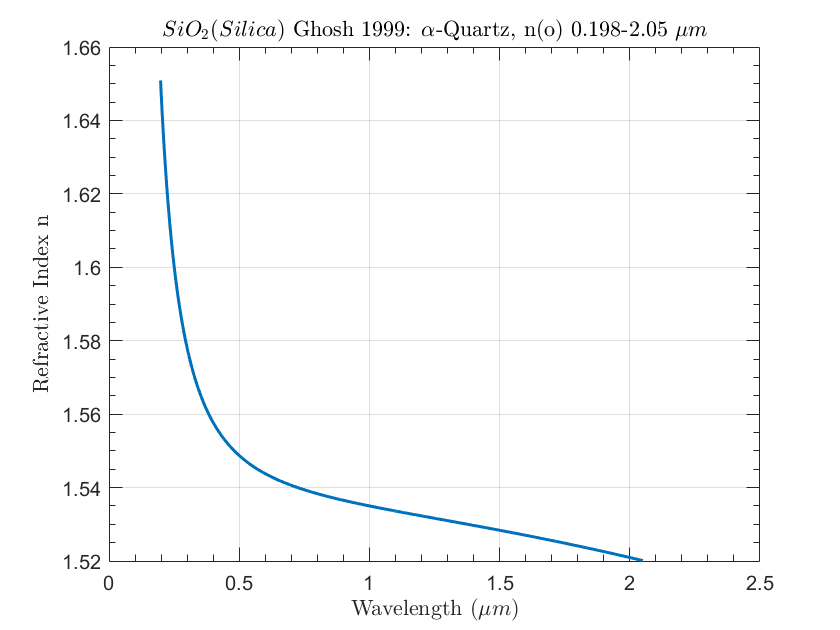

% Citation:
% Ghosh, S. (1999). Dispersion-equation coefficients for the 
% refractive index and birefringence of calcite and quartz crystals. 
% *Journal of Applied Physics*, 86(8), 3950-3953.
% https://doi.org/10.1063/1.370157

% Define wavelength range in micrometers
x = linspace(0.198, 2.05, 1000);

% Define refractive index function n(x)
n = sqrt(1 + 0.28604141 + 1.07044083 ./ (1 - 1.00585997e-2 ./ x.^2) + 1.10202242 ./ (1 - 100 ./ x.^2));

% Plot the refractive index as a function of wavelength
figure;
plot(x, n, 'LineWidth', 1.5);
xlabel('Wavelength $(\mu m)$', "Interpreter","latex");
ylabel('Refractive Index n', "Interpreter","latex");
title('$SiO_2 (Silica)$ Ghosh 1999: $\alpha$-Quartz, n(o) 0.198-2.05 $\mu m$', "Interpreter","latex");
grid on;
box on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
         'TickLength', [0.02, 0.04], ...
         'LineWidth', 0.5);

% Target wavelength in micrometers
target_wavelength = 1.064;

% Step size for finite difference
h = 1e-5;

% Evaluate derivatives beta_1 to beta_10 using central difference
beta = zeros(1, 10); % Array to store beta_1 to beta_10
for order = 1:10
    beta(order) = central_diff(@(x) sqrt(1 + 0.28604141 + 1.07044083 ./ (1 - 1.00585997e-2 ./ x.^2) ...
        + 1.10202242 ./ (1 - 100 ./ x.^2)), target_wavelength, order, h);
end

% Display the derivatives
for k = 1:10
    fprintf('Beta_%d at 1064 nm: %.5e \n', k, beta(k));
end

Beta_1 at 1064 nm: -1.37509e-02 
Beta_2 at 1064 nm: 9.11937e-03 
Beta_3 at 1064 nm: 2.22045e-01 
Beta_4 at 1064 nm: -1.11022e+04 
Beta_5 at 1064 nm: -1.38778e+09 
Beta_6 at 1064 nm: 2.77556e+13 
Beta_7 at 1064 nm: 1.04083e+19 
Beta_8 at 1064 nm: -6.83594e+07 
Beta_9 at 1064 nm: -9.19403e+28 
Beta_10 at 1064 nm: -1.04083e+33 



% Central difference method for nth derivative

function d_n = central_diff(f, x, n, h)
    if n == 1
        d_n = (f(x + h) - f(x - h)) / (2 * h);
    elseif n == 2
        d_n = (f(x + h) - 2 * f(x) + f(x - h)) / (h^2);
    else
        % Higher order derivatives using recursive finite difference
        d_n = (central_diff(f, x + h, n - 1, h) - central_diff(f, x - h, n - 1, h)) / (2 * h);
    end
end
